# [Example 2.1]  지시된 구간에서 다음 신호를 각각 만들고 그려라.

#### a. x(n) = 2*delta(n+2) - delta(n-4),  -5 <= n <= 5

n = -5:5;
x = 2*impseq(-2,-5,5) - impseq(4,-5,5);
subplot(2,2,1)
stem(n,x);  ylim([-2,3]);
title('Sequence in Problem 2.1a');  xlabel('n');    ylabel('x(n)');

#### b. x(n) = n[u(n) - u(n-10)] + 10e^(-0.3*(n-10))*[u(n-10) - u(n-20)],  0<= n <=20

n = 0:20;
x1 = n.*(stepseq(0,0,20) - stepseq(10,0,20));
x2 = 10*exp(-0.3*(n-10)).*(stepseq(10,0,20) - stepseq(20,0,20));
x = x1 + x2;

subplot(2,2,2);
stem(n,x);  ylim([-1,11]);
title('Sequence in Problem 2.1b');  xlabel('n');    ylabel('x(n)');

#### c. x(n) = cos(0.04*pi*n) + 0.2*w(n),  0 <= n <= 50

n = 0:50;
x = cos(0.04*pi*n) + 0.2*randn(size(n));

subplot(2,2,3);
stem(n,x);  xlim([0, 50]);
title('Sequence in Problem 2.1c');  xlabel('n');    ylabel('x(n)');

#### d. xtilde(n) = {...., 5, 4, 3,2, 1, 5(n= 0), 4, 3, 2, 1, 5, 4, 3, 2, 1, ...};  -10 <= n <= 9

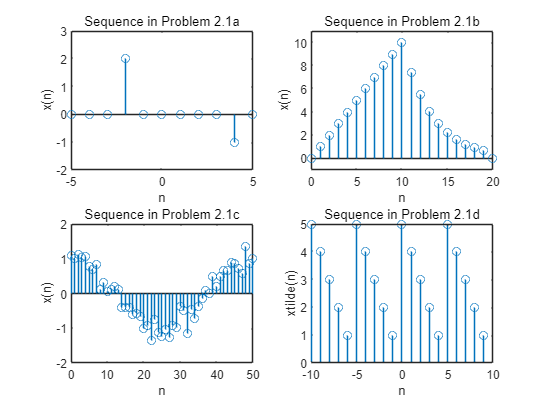

n = -10:9;
x = [5,4,3,2,1];
xtilde = x' * ones(1,4);
xtilde = (xtilde(:))';

subplot(2,2,4);
stem(n, xtilde);
title('Sequence in Problem 2.1d');  xlabel('n');    ylabel('xtilde(n)');